% SHAPC-Mean and SHAPC-Var Comparison
algs = ["iTAML", "RPSnet", "foster", "memo", "der"];
dataset = 'cifar10';

if isfile("cifar10_shapc_data.mat")
    load("cifar10_shapc_data.mat")
else
    cifar10_shapc_data = struct();
end

% Load SHAPC values (Full)
for i=1:length(algs)
    alg = algs(i);
    save_path = sprintf("%s/%s/shapc_vals_full.mat", alg, dataset);
    if isfile(save_path)
        shapc_struct = load(save_path);
        num_sessions = 5;
       
        % Load SHAPC values all
        shapc_avgs = [];
        for i=1:num_sessions-1
            for j=i:num_sessions-1
                pair_str = 'sc' + string(i-1) +string(j);
                shapcs = [];
                for k=1:length(fieldnames(shapc_struct.(pair_str)))
                    sample_str = 'sample' + string(k-1);
                    shapcs = [shapcs; shapc_struct.(pair_str).(sample_str)];
                end
                shapc_avgs = [shapc_avgs; mean(shapcs)];
        
            end
        end
        
        % Note the shapc is represented as percentage
        %disp("From averaging all tasks together:")
        shapc_mean_perc = mean(shapc_avgs);
        shapc_mean = mean(shapc_avgs) / 100;
    else
        shapc_mean_perc = NaN;
        shapc_mean = NaN;
    end
    cifar10_shapc_data.(alg).full_shapc = shapc_mean_perc;
end
save("cifar10_shapc_data.mat", "cifar10_shapc_data")

% Create Table
full_shapcs = [];
full_times = [];
for i=1:length(algs)
    alg = algs(i);
    full_shapcs = [full_shapcs; cifar10_shapc_data.(alg).full_shapc];
    full_times = [full_times; cifar10_shapc_data.(alg).full_time];
end

% Load SHAPC values (First and Last Only)
for i=1:length(algs)
    alg = algs(i);
    save_path = sprintf("%s/%s/shapc_vals_first_last.mat", alg, dataset);
    if isfile(save_path)
        shapc_struct = load(save_path);
        num_sessions = 5;
       
        % Load SHAPC values all
        shapc_avgs = [];
        for i=1:num_sessions-1
            for j=4
                pair_str = 'sc' + string(i-1) +string(j);
                shapcs = [];
                sample_list = string(fieldnames(shapc_struct.(pair_str)));
                for k=1:length(fieldnames(shapc_struct.(pair_str)))
                    sample_str = sample_list(k);%'sample' + string(k-1);
                    shapcs = [shapcs; shapc_struct.(pair_str).(sample_str)];
                end
                shapc_avgs = [shapc_avgs; mean(shapcs)];
        
            end
        end
        
        % Note the shapc is represented as percentage
        %disp("From averaging all tasks together:")
        shapc_mean_perc = mean(shapc_avgs);
        shapc_mean = mean(shapc_avgs) / 100;
    else
        shapc_mean_perc = NaN;
        shapc_mean = NaN;
    end
    cifar10_shapc_data.(alg).first_last_shapc = shapc_mean_perc;
end
save("cifar10_shapc_data.mat", "cifar10_shapc_data")

% Create Table
first_last_shapcs = [];
first_last_times = [];
for i=1:length(algs)
    alg = algs(i);
    first_last_shapcs = [first_last_shapcs; cifar10_shapc_data.(alg).first_last_shapc];
    first_last_times = [first_last_times; cifar10_shapc_data.(alg).first_last_time];
end

% Load SHAPC values (Full 1000)
for i=1:length(algs)
    alg = algs(i);
    save_path = sprintf("%s/%s/shapc_vals_full_1000.mat", alg, dataset);
    if isfile(save_path)
        shapc_struct = load(save_path);
        num_sessions = 5;
       
        % Load SHAPC values all
        shapc_avgs = [];
        for i=1:num_sessions-1
            for j=i:num_sessions-1
                pair_str = 'sc' + string(i-1) +string(j);
                shapcs = [];
                for k=1:length(fieldnames(shapc_struct.(pair_str)))
                    sample_str = 'sample' + string(k-1);
                    shapcs = [shapcs; shapc_struct.(pair_str).(sample_str)];
                end
                shapc_avgs = [shapc_avgs; mean(shapcs)];
        
            end
        end
        
        % Note the shapc is represented as percentage
        %disp("From averaging all tasks together:")
        shapc_mean_perc = mean(shapc_avgs);
        shapc_mean = mean(shapc_avgs) / 100;
    else
        shapc_mean_perc = NaN;
        shapc_mean = NaN;
    end
    cifar10_shapc_data.(alg).full_1000_shapc = shapc_mean_perc;
end
save("cifar10_shapc_data.mat", "cifar10_shapc_data")

% Create Table
full_1000_shapcs = [];
full_1000_times = [];
for i=1:length(algs)
    alg = algs(i);
    full_1000_shapcs = [full_1000_shapcs; cifar10_shapc_data.(alg).full_1000_shapc];
    full_1000_times = [full_1000_times; cifar10_shapc_data.(alg).full_1000_time];
end

% Load SHAPC values (First/Last 1000)
for i=1:length(algs)
    alg = algs(i);
    save_path = sprintf("%s/%s/shapc_vals_first_last_1000.mat", alg, dataset);
    if isfile(save_path)
        shapc_struct = load(save_path);
        num_sessions = 5;
       
        % Load SHAPC values all
        shapc_avgs = [];
        for i=1:num_sessions-1
            for j=4
                pair_str = 'sc' + string(i-1) +string(j);
                shapcs = [];
                sample_list = string(fieldnames(shapc_struct.(pair_str)));
                for k=1:length(fieldnames(shapc_struct.(pair_str)))
                    sample_str = sample_list(k);%'sample' + string(k-1);
                    shapcs = [shapcs; shapc_struct.(pair_str).(sample_str)];
                end
                shapc_avgs = [shapc_avgs; mean(shapcs)];
        
            end
        end
        
        % Note the shapc is represented as percentage
        %disp("From averaging all tasks together:")
        shapc_mean_perc = mean(shapc_avgs);
        shapc_mean = mean(shapc_avgs) / 100;
    else
        shapc_mean_perc = NaN;
        shapc_mean = NaN;
    end
    cifar10_shapc_data.(alg).first_last_1000_shapc = shapc_mean_perc;
end
save("cifar10_shapc_data.mat", "cifar10_shapc_data")

% Create Table
first_last_1000_shapcs = [];
first_last_1000_times = [];
for i=1:length(algs)
    alg = algs(i);
    first_last_1000_shapcs = [first_last_1000_shapcs; cifar10_shapc_data.(alg).first_last_1000_shapc];
    first_last_1000_times = [first_last_1000_times; cifar10_shapc_data.(alg).first_last_1000_time];
end

% Compare Methods
rows = algs;

columns = ["Full" "First/Last" "Full 1000" "First/Last 1000"];
shapc_table_comp = table(full_shapcs, first_last_shapcs, full_1000_shapcs, ...
    first_last_1000_shapcs,'VariableNames', columns, 'RowNames', rows)

shapc_table_comp = 5×4 table
               Full     First/Last    Full 1000    First/Last 1000
              ______    __________    _________    _______________

    iTAML     31.813      31.596       31.663          31.073     
    RPSnet       NaN         NaN       23.113          23.217     
    foster    26.809      28.397       26.694          28.713     
    memo      28.594      29.604       28.748          29.583     
    der       39.395       42.03       39.151          41.909     



columns = ["Full" "First/Last" "Full 1000" "First/Last 1000"];
time_table_comp = table(full_times, first_last_times, full_1000_times, ...
    first_last_1000_times, 'VariableNames', columns, 'RowNames', rows)

time_table_comp = 5×4 table
               Full     First/Last    Full 1000    First/Last 1000
              ______    __________    _________    _______________

    iTAML     10.306      7.4725       0.73667         0.57083    
    RPSnet       NaN         NaN           NaN             NaN    
    foster    11.046      7.0719       0.96222         0.50417    
    memo      9.2156      6.7903         0.785         0.68417    
    der       21.039      7.3558        2.1825          1.5094    



%abs_diffs = [ful]

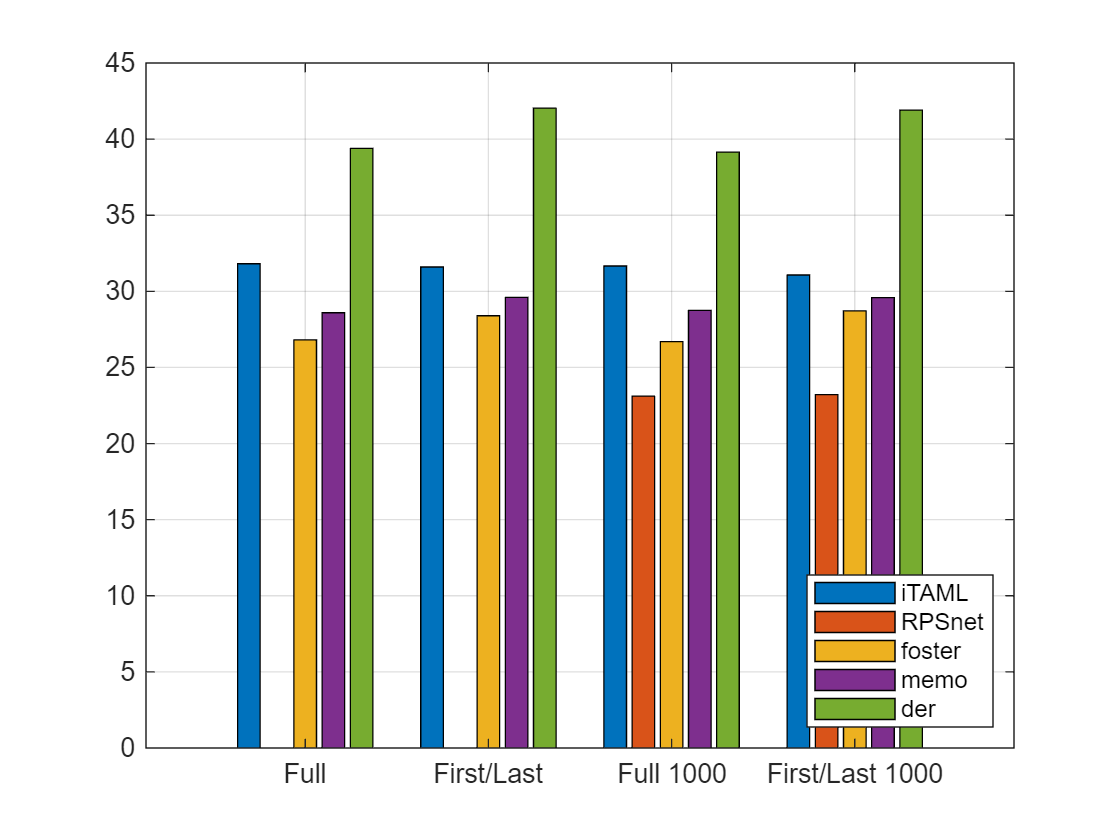

% Create Graph
Y = [full_shapcs'; first_last_shapcs'; 
    full_1000_shapcs'; first_last_1000_shapcs'];
bar(columns, Y)
legend(algs, 'Location', 'southeast')
grid on